
clear all;
clc;

% caract
g = 9.81;

% Drag matrix from jean notes
Dx = 0.15;
Dy = 0.15;
Dz = 0.25;
D = diag([Dx, Dy, Dz]);

% Hover linearized A matrix
A = [ zeros(3,3), zeros(3,3), eye(3),    zeros(3,3);
      zeros(3,3), zeros(3,3), zeros(3,3), eye(3);
      zeros(3,3), [0 g 0; -g 0 0; 0 0 0], -D, zeros(3,3);
      zeros(3,3), zeros(3,3), zeros(3,3), zeros(3,3) ];

disp('A = ');

A = 


disp(A);

         0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0    9.8100         0   -0.1500         0         0         0         0         0
         0         0         0   -9.8100         0         0         0   -0.1500         0         0         0         0
         0         0         0  


lambda = eig(A);

disp('Eigenvalues of A = ');

Eigenvalues of A = 


disp(lambda);

         0
         0
         0
   -0.1500
         0
   -0.1500
         0
         0
   -0.2500
         0
         0
         0



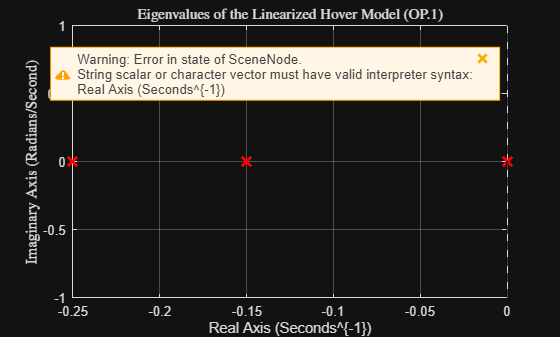




% Plotting eig in the complexo plane
figure;
plot(real(lambda), imag(lambda), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
title('Eigenvalues of the Linearized Hover Model (OP.1)');
xlabel('Real Axis (Seconds^{-1})');
ylabel('Imaginary Axis (Radians/Second)');
xline(0, 'k--', 'LineWidth', 1.5); 



% Agora for the flight mode

%% caract
g = 9.81;
% Crazyflie 2.1 Physical Parameters
m = 0.027;
%still dont know how the mass affects (REMOVER)

% Moment of Inertia Matrix (J)
Jx = 1.66e-5; 
Jy = 1.66e-5; 
Jz = 2.93e-5; 
J = diag([Jx, Jy, Jz]);

% Drag matrix, igual a outra
Dx = 0.15;
Dy = 0.15;
Dz = 0.25;
D = diag([Dx, Dy, Dz]);

%% Horizontal-flight eq values
% Replace these with the equilibrium values you obtained
phi_e   = 0.0;  % roll
theta_e = 0.1;  % pitch
psi_e   = 0.0;  % yaw 

vx_e = 1.0;  %veloc m/s
vy_e = 0.0;
vz_e = 0.0;

v_e = [vx_e; vy_e; vz_e];

%Lib Francisco - Sen Cos 
cphi = cos(phi_e);    sphi = sin(phi_e);
cth  = cos(theta_e);  sth  = sin(theta_e);
cpsi = cos(psi_e);    spsi = sin(psi_e);

%%%%%%%%%%%%%%%%%%%%% Rotation matrix at equilibrium
R_e = [ cth*cpsi,  sphi*sth*cpsi - cphi*spsi,  cphi*sth*cpsi + sphi*spsi;
        cth*spsi,  sphi*sth*spsi + cphi*cpsi,  cphi*sth*spsi - sphi*cpsi;
        -sth,      sphi*cth,                   cphi*cth                  ];

%%%%%%%%%%%%%%%%%%%% Euler matrix at equilibrium
Q_e = [ 1,  sphi*tan(theta_e),  cphi*tan(theta_e);
        0,  cphi,              -sphi;
        0,  sphi/cth,           cphi/cth ];
dR_dphi = [ 0,  cphi*sth*cpsi + sphi*spsi,  -sphi*sth*cpsi + cphi*spsi;
            0,  cphi*sth*spsi - sphi*cpsi,  -sphi*sth*spsi - cphi*cpsi;
            0,  cphi*cth,                   -sphi*cth ];
dR_dtheta = [ -sth*cpsi,   sphi*cth*cpsi,   cphi*cth*cpsi;
              -sth*spsi,   sphi*cth*spsi,   cphi*cth*spsi;
              -cth,       -sphi*sth,       -cphi*sth ];
dR_dpsi = [ -cth*spsi,  -sphi*sth*spsi - cphi*cpsi,  -cphi*sth*spsi + sphi*cpsi;
             cth*cpsi,   sphi*sth*cpsi - cphi*spsi,   cphi*sth*cpsi + sphi*spsi;
             0,          0,                              0 ];
A_p_lambda = [dR_dphi*v_e, dR_dtheta*v_e, dR_dpsi*v_e];

A_v_lambda = [ 0,                    g*cos(theta_e),                  0;
              -g*cos(phi_e)*cos(theta_e),  g*sin(phi_e)*sin(theta_e), 0;
               g*sin(phi_e)*cos(theta_e),  g*cos(phi_e)*sin(theta_e), 0 ];
S_ve = [   0,    -vz_e,   vy_e;
         vz_e,      0,   -vx_e;
        -vy_e,    vx_e,     0 ];
%make this more easy to read (REMOVER)


%% Assemble A_hf
A_hf = [ zeros(3,3), A_p_lambda, R_e,         zeros(3,3);
         zeros(3,3), zeros(3,3), zeros(3,3),  Q_e;
         zeros(3,3), A_v_lambda, -D,          S_ve;
         zeros(3,3), zeros(3,3), zeros(3,3),  zeros(3,3) ];

disp('A_hf = ');

A_hf = 


disp(A_hf);

         0         0         0         0   -0.0998         0    0.9950         0    0.0998         0         0         0
         0         0         0         0         0    0.9950         0    1.0000         0         0         0         0
         0         0         0         0   -0.9950         0   -0.0998         0    0.9950         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0    0.1003
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0         0         0         0    1.0050
         0         0         0         0    9.7610         0   -0.1500         0         0         0         0         0
         0         0         0   -9.7610         0         0         0   -0.1500         0         0         0   -1.0000
         0         0         0  


lambda_hf = eig(A_hf);

disp('Eigenvalues of A_hf = ');

Eigenvalues of A_hf = 


disp(lambda_hf);

         0
         0
         0
   -0.1500
         0
   -0.2500
   -0.1500
         0
         0
         0
         0
         0



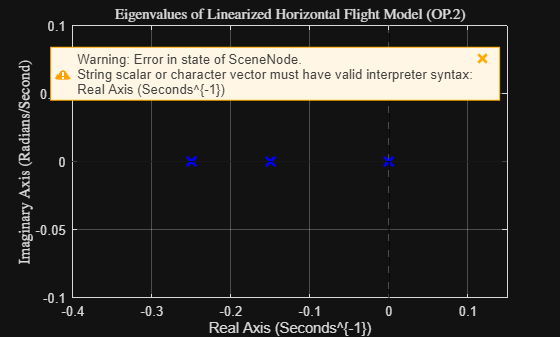




%% Plotting eigenvalues in the complex plane (OP.2)
figure;
plot(real(lambda_hf), imag(lambda_hf), 'bx', 'MarkerSize', 10, 'LineWidth', 2);
hold on;
xline(0, 'k--', 'LineWidth', 1.5); 
yline(0, 'k-', 'LineWidth', 0.5);  
grid on;
title('Eigenvalues of Linearized Horizontal Flight Model (OP.2)');
xlabel('Real Axis (Seconds^{-1})');
ylabel('Imaginary Axis (Radians/Second)');
margin_x = max(abs(real(lambda_hf))) * 0.2 + 0.1;
margin_y = max(abs(imag(lambda_hf))) * 0.2 + 0.1;
xlim([min(real(lambda_hf)) - margin_x, max(real(lambda_hf)) + margin_x]);
ylim([min(imag(lambda_hf)) - margin_y, max(imag(lambda_hf)) + margin_y]);





disp('end 1.8')

end 1.8


% now this following code ior for 1.9




% Assuming J = diag([Jx, Jy, Jz]);

B = [ zeros(3,1),  zeros(3,3);      
      zeros(3,1),  zeros(3,3);      
      0,           0,   0,   0;    
      0,           0,   0,   0;
      1/m,         0,   0,   0;     
      zeros(3,1),  inv(J) ];        

% measuring position 1-3 and attitude 4-6
C = [ eye(3),     zeros(3,3), zeros(3,3), zeros(3,3); 
      zeros(3,3), eye(3),     zeros(3,3), zeros(3,3) ];

% controllability
Co = ctrb(A_hf, B);
disp(Co)

   1.0e+05 *

         0         0         0         0    0.0000         0         0         0   -0.0000         0    0.0000         0    0.0000         0    5.8946         0   -0.0000         0   -0.8886         0    0.0000         0    0.1344         0   -0.0000         0   -0.0204         0    0.0000         0    0.0031         0   -0.0000         0   -0.0005         0    0.0000         0    0.0001         0   -0.0000         0   -0.0000         0    0.0000         0    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0   -5.8801         0   -0.2831         0    0.8820         0    0.0425         0   -0.1323         0   -0.0064         0    0.0198         0    0.0010         0   -0.0030         0   -0.0001         0    0.0004         0    0.0000         0   -0.0001         0   -0.0000         0    0.0000         0    0.0000         0   -0.0000         0   -0.0000
         0         0    

rank_Co = rank(Co);
disp(['Rank of Controllability Matrix: ', num2str(rank_Co)]);

Rank of Controllability Matrix: 12


disp('If rank_Co == 12, the system is fully controllable')

If rank_Co == 12, the system is fully controllable



% Observability
Ob = obsv(A_hf, C);
disp(Ob)

    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0   -0.0998         0    0.9950         0    0.0998         0         0         0
         0         0         0         0         0    0.9950         0    1.0000         0         0         0         0
         0         0         0  

rank_Ob = rank(Ob);
disp(['Rank of Observability Matrix: ', num2str(rank_Ob)]);

Rank of Observability Matrix: 12


disp('If rank_Ob == 12, the system is fully observable.')

If rank_Ob == 12, the system is fully observable.



%display the controlabilty and obsevability matrix 
% Displaying the first block of the Controllability matrix (The B matrix)
disp('First block of Controllability Matrix (B):');

First block of Controllability Matrix (B):


disp(Co(:, 1:4)); 

   1.0e+04 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0037         0         0         0
         0    6.0241         0         0
         0         0    6.0241         0
         0         0         0    3.4130




% Displaying the second block of the Controllability matrix (AB)
disp('Second block of Controllability Matrix (AB):');

Second block of Controllability Matrix (AB):


disp(Co(:, 5:8)); 

   1.0e+04 *

    0.0004         0         0         0
         0         0         0         0
    0.0037         0         0         0
         0    6.0241         0    0.3424
         0         0    6.0241         0
         0         0         0    3.4301
         0         0         0         0
         0         0         0   -3.4130
   -0.0009         0    6.0241         0
         0         0         0         0
         0         0         0         0
         0         0         0         0




% Displaying the first block of the Observability matrix (C)
disp('First block of Observability Matrix (C):');

First block of Observability Matrix (C):


disp(Ob(1:6, :));

     1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0



%we are not going to display this part in the report, matrix demasiado
%grande 

disp('end of 1.9')

end of 1.9



%1.10 tranfer functions
disp('task 1.10')

task 1.10




display("exercicio 1.10")

    "exercicio 1.10"






C_full = eye(12);
D_full = zeros(12, 4);


sys_hover = ss(A, B, C_full, D_full);


% tf_sys is (12 outputs, 4 inputs)
tf_sys = tf(sys_hover);
%%%%%% change 

G_nx_phi = tf_sys(4, 2);


G_ny_theta = tf_sys(5, 3);


G_nz_psi = tf_sys(6, 4);

G_T_pz = tf_sys(3, 1);

G_phi_py = minreal(tf_sys(2, 2) / tf_sys(4, 2));

G_theta_px = minreal(tf_sys(1, 3) / tf_sys(5, 3));

%% display the results
disp(' ');

disp('--- Inner Loops ---');

--- Inner Loops ---


disp('G_nx_phi(s) = '); zpk(G_nx_phi)

G_nx_phi(s) = 

ans =
 
  60241
  -----
   s^2
 
Continuous-time zero/pole/gain model.


disp('G_ny_theta(s) = '); zpk(G_ny_theta)

G_ny_theta(s) = 

ans =
 
  60241
  -----
   s^2
 
Continuous-time zero/pole/gain model.


disp('G_nz_psi(s) = '); zpk(G_nz_psi)

G_nz_psi(s) = 

ans =
 
  34130
  -----
   s^2
 
Continuous-time zero/pole/gain model.



disp('--- Altitude Loop ---');

--- Altitude Loop ---


disp('G_T_pz(s) = '); zpk(G_T_pz)

G_T_pz(s) = 

ans =
 
    37.037
  ----------
  s (s+0.25)
 
Continuous-time zero/pole/gain model.



disp('--- Outer Loops ---');

--- Outer Loops ---


disp('G_phi_py(s) = '); zpk(G_phi_py)

G_phi_py(s) = 

ans =
 
    -9.81
  ----------
  s (s+0.15)
 
Continuous-time zero/pole/gain model.


disp('G_theta_px(s) = '); zpk(G_theta_px)

G_theta_px(s) = 

ans =
 
     9.81
  ----------
  s (s+0.15)
 
Continuous-time zero/pole/gain model.




disp('end 1.10')

end 1.10


%1.11 root locus analysis
disp('task1.11')

task1.11



display("1<.11 root locus")

    "1<.11 root locus"



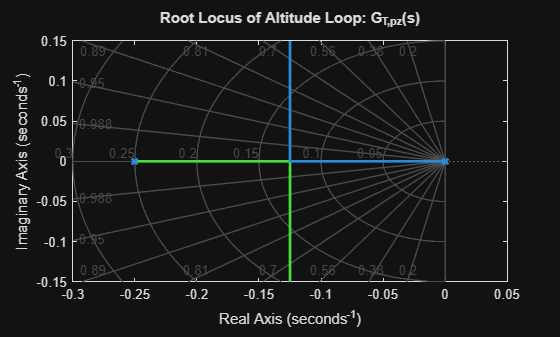

% Plot Root Locus for Altitude Loop
figure;
rlocus(G_T_pz);
title('Root Locus of Altitude Loop: G_{T,pz}(s)');
grid on;

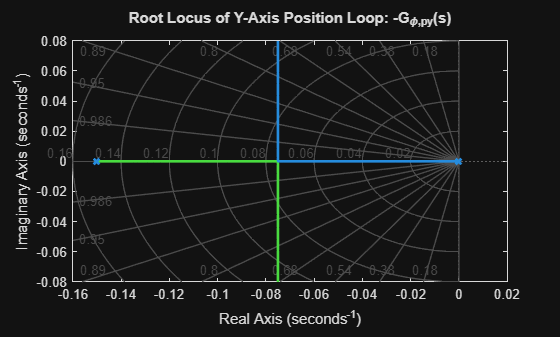


% Plot Root Locus for Y-Axis Loop
figure;
rlocus(-G_phi_py); 
title('Root Locus of Y-Axis Position Loop: -G_{\phi,py}(s)');
grid on;